clearvars
addpath('Complex_Wave_ISM/');
addpath('Least_Mean_Square/');
addpath('Complex_Wave_ISM/ISM/');

### Initial parameters for ISM

% -------------------------
% --------- Grid ----------
L = [10,10,10]; % Room dimensions (x,y,z)
spacing = 1; % (m) Spacing between each point of the grid
% ------ Time array -------
f = 150; % [Hz] frequency
Fs = 32*f; % Sampling frequency - Oversampling rate of 32 (see nyquist theorem)
Ls = 3000; % Signal length
Ts = 1/Fs; % Time step
t = (0:Fs-1)*Ts; % Time array
% -------------------------
% ------ Positions --------
S1 = [5,0,0]; % (x,y,t) Noise - Source coordinates
S2 = [3,3,0]; % (x,y,t) Anti-Noise - Source coordinates
R = [0,0,0]; % (x,y,z) Receiver coordinates
% -------------------------
% ---- Wave Equation ------
c = 343; % (m/s) Speed of sound
alpha = [0 0 0 0 0 0]; % Absorption coefficient
U0 = 0.001; % Radial velocity
a = 1; % Radius of emitting sphere
Q = 4*pi*a^2*U0; % Source strength
rho = 1.125; % Density of air
% -------------------------
% --------- IMS -----------
image_order = 0;

### LMS input signal

As an noise signal we will for now use a simple 150 Hz sine wave. This signal needs to be decomposed into its fundamental sine waves.

x = sin(2*pi*f*t); % Noise signal
[x_f, x_mag,x_sine_waves] = decompose_wave(x,t,Fs,Ts,0.001);

And those sine waves resp. their frequency need to fed into the image source model (IMS) to compute the output pressure received at the error microphone from this source.

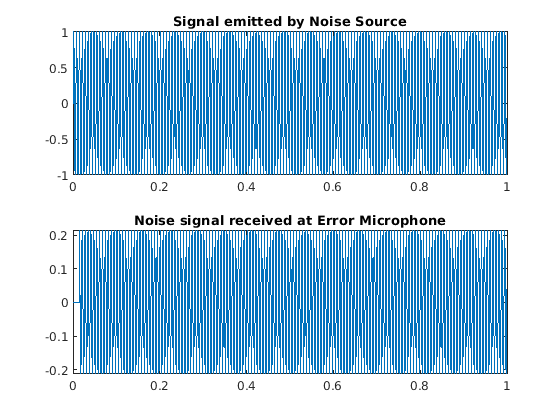

x_out_p = zeros(1,length(t));
for i=1:length(x_f)
    x_out_p = x_out_p + image_source_pressure_wave(S1,R,L,t,spacing,c,x_f(i),x_mag(i),Q,rho,image_order,alpha,0);
end
figure;
subplot(211);
plot(t,x);
title("Signal emitted by Noise Source");
subplot(212);
plot(t,x_out_p);
title("Noise signal received at Error Microphone");

### LMS for Anti-Noise signal directly at Error Microphone

For now we suppose that the secondary source which produces the anti-noise single is situated directly at the error microphone. With that in mind we execute the least-mean-square algorithm.

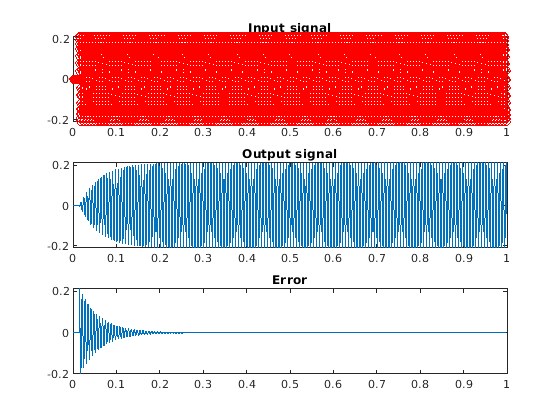

d = 0 * t; % Reference signal - Silence
mu = 0.1; % Step size
M=1; % Length of signal fragment used for computation at each step

N=length(t);
%inital values: 0
w=zeros(1,M);
y = zeros(1,N);
e = zeros(1,N);
%number of samples of the input signal

%LMS
for i=M:N
    y(i) = w*x_out_p(i-M+1:1:i)';
    e(i)=x_out_p(i)+y(i);
    w = w-2*mu*e(i)*x_out_p(i-M+1:1:i);
end
ee = x_out_p + y;

figure;
subplot(311);
plot(t,x_out_p,'r-o');
title("Input signal");
subplot(312);
plot(t,y);
title("Output signal");
subplot(313);
plot(t,ee);
title("Error");

The step size **mu** and the signal fragment length **M** should be modified to optain the optimal result.

### LMS for Anti-Noise at different position

Now comes the harder part. Obviously the secondary source needs to be at a position that is different than the error signal. Which position would be the optimal is a good question, however it will have to wait. 

For now we will set the Secondary Source at a position that is oposite the primary source in respect to the error microphone, thus expecting a phase shifted signal.

Lets first observe what fundamental sine waves a phase shifted (180° - pi) signal would produce.

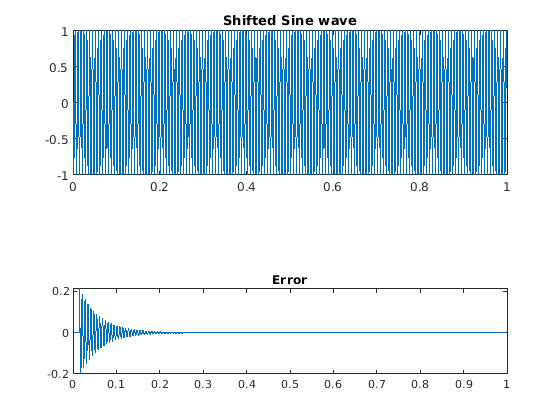

x_shift = sin(2*pi*f*t + pi);
[x_shift_f, x_shift_mag, x_shift_sine_waves] = decompose_wave(x_shift,t,Fs,Ts,0.0001);
subplot(211);
plot(t,x_shift);
title("Shifted Sine wave");

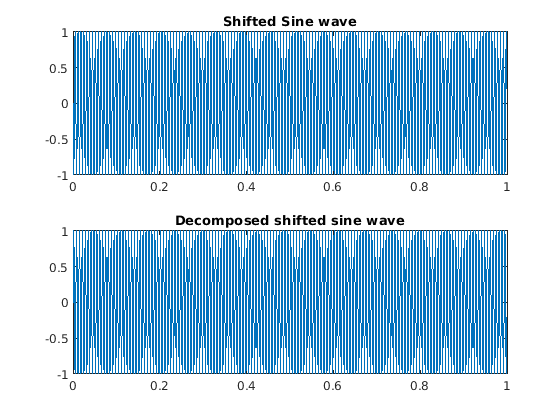

subplot(212);
plot(t,x_shift_sine_waves);
title("Decomposed shifted sine wave");

The function does not return the original function, it seems to be shifted.

When executing the decompose_wave function on the phase shifted sine wave, we've noticed that the function needs to be adapted in order to retain the information about the phase of the signal, otherwise the output is a non-shifted sine wave.

### Obtaining magnitude and phase from FFT

We will follow this tutorial: [https://www.gaussianwaves.com/2015/11/interpreting-fft-results-obtaining-magnitude-and-phase-information/](https://www.gaussianwaves.com/2015/11/interpreting-fft-results-obtaining-magnitude-and-phase-information/) to extract the magnitude and phase from the matlab FFT function

#### Represent signal in discrete time-domain

A = 0.5; %amplitude of the cosine wave
fc=10;%frequency of the cosine wave
phase=30; %desired phase shift of the cosine in degrees
fs=32*fc;%sampling frequency with oversampling factor 32
tc=0:1/fs:2-1/fs;%2 seconds duration

phi = phase*pi/180; %convert phase shift in degrees in radians
x=A*cos(2*pi*fc*tc+phi);%time domain signal with phase shift

figure; 
subplot(511);
plot(tc,x); %plot the signal
title("Original cosine wave");
xlabel("time [s]"); ylabel("x(t)");

#### Represent signal in frequency domain

N=length(x); %FFT size
X = 1/N*fftshift(fft(x,N));%N-point complex DFT

#### Extract amplitude of frequency component

df=fs/N; %frequency resolution
sampleIndex = -N/2:N/2-1; %ordered index for FFT plot
freq=sampleIndex*df; %x-axis index converted to ordered frequencies
subplot(512);
stem(freq,abs(X)); %magnitudes vs frequencies
title("Amplitude spectrum");
xlabel('f (Hz)'); ylabel('|X(k)|');

#### Extract phase of frequency component

phase=atan2(imag(X),real(X))*180/pi; %phase information
subplot(513);
plot(freq,phase); %phase vs frequencies
title("Phase spectrum");
xlabel("f (Hz)"); ylabel('phase X(k)');

Filter the phase value below a certain threshold

X2=X;%store the FFT results in another array
%detect noise (very small numbers (eps)) and ignore them
threshold = max(abs(X))/10000; %tolerance threshold
X2(abs(X)<threshold) = 0; %maskout values that are below the threshold
phase=atan2(imag(X2),real(X2))*180/pi; %phase information
subplot(514);
plot(freq,phase); %phase vs frequencies
title("Phase spectrum - Threshold");
xlabel("f (Hz)"); ylabel('phase X(k)');

#### Reconstruct the time domain signal

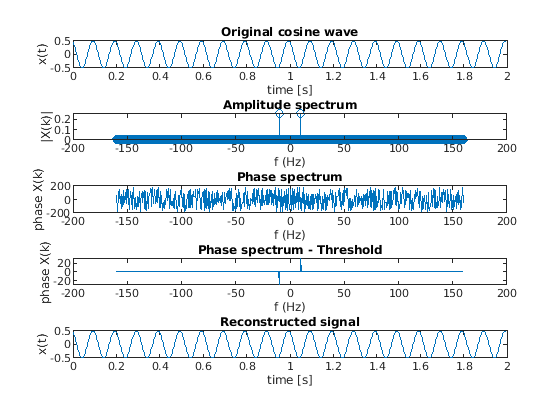

x_recon = N*ifft(ifftshift(X),N); %reconstructed signal
tc = [0:1:length(x_recon)-1]/fs; %recompute time index 
subplot(515);
plot(tc,x_recon);%reconstructed signal
title("Reconstructed signal");
xlabel("time [s]"); ylabel("x(t)");

### Complex wave decomposition with phase

We implemented a new function to decompose a complex signal which additionaly outputs the phase information of the fundamental sine waves

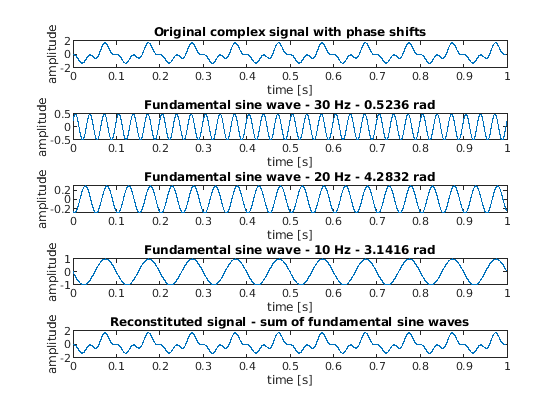

figure;
x_shift = 1*sin(2*pi*10*t + pi) + 0.5*sin(2*pi*30*t + pi/6) + 0.3 * sin(2*pi*20*t - 2);
[x_shift_f,x_shift_mag,x_shift_phase,x_shift_sine_waves] = phase_decompose_wave(x_shift,t,Fs,Ts);
decom_size = size(x_shift_sine_waves,1);
subplot(decom_size+2,1,1);
plot(t,x_shift);
title("Original complex signal with phase shifts");
xlabel("time [s]"); ylabel("amplitude");
for i=1:decom_size
    subplot(decom_size+2,1,i+1);
    plot(t,x_shift_sine_waves(i,:));
    title("Fundamental sine wave - " + x_shift_f(i) + " Hz - " + x_shift_phase(i) + " rad");
    xlabel("time [s]"); ylabel("amplitude");
end
subplot(decom_size+2,1,decom_size+2);
plot(t,sum(x_shift_sine_waves));
title("Reconstituted signal - sum of fundamental sine waves");
xlabel("time [s]"); ylabel("amplitude");

It seems like the new decomposition function is working.

### LMS for Anti-Noise at different position (resume)

The image source method has been adapted to also include the signals phase.

We have implemented the function phase_complex_wave_ism which decomposes the signal in its fundamental sine waves and then executed the image source model for each of thosed wave and then outputs the sum of resulting output pressures.

Lets test it by placing the primary and the secondary source on opposite sides of the error microphone and emitting a complex signal as primary source and resp. a 180° phase shifted signal at the secondary source. We are expecting that when adding the resulting output pressures at the microphone to obtain a null signal (or something close to null).

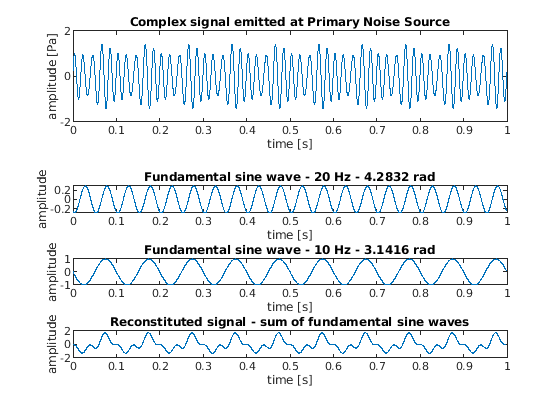

image_order = 15;
R = [0,0,0]; % Error microphone
S1 = [5,0,0]; % Primary sound source - Noise
S2 = [-5,0,0]; % Secondary sound source - Anti-Noise
S1_wave = 1*sin(2*pi*50*t) + 0.3*sin(2*pi*40*t + pi) + 0.4*sin(2*pi*60*t + pi/4);
S2_wave = 1*sin(2*pi*50*t + pi) + 0.3*sin(2*pi*40*t + pi + pi) + 0.4*sin(2*pi*60*t + pi/4 + pi); % S1 shifted by 180° (pi)
S1_out_p = phase_complex_wave_ism(S1_wave,S1,R,L,t,Fs,Ts,spacing,c,Q,rho,image_order,alpha,0);
S2_out_p = phase_complex_wave_ism(S2_wave,S2,R,L,t,Fs,Ts,spacing,c,Q,rho,image_order,alpha,0);
R_out_p = S1_out_p + S2_out_p;
subplot(311);
plot(t,S1_wave);
title("Complex signal emitted at Primary Noise Source");
xlabel("time [s]"); ylabel("amplitude [Pa]");

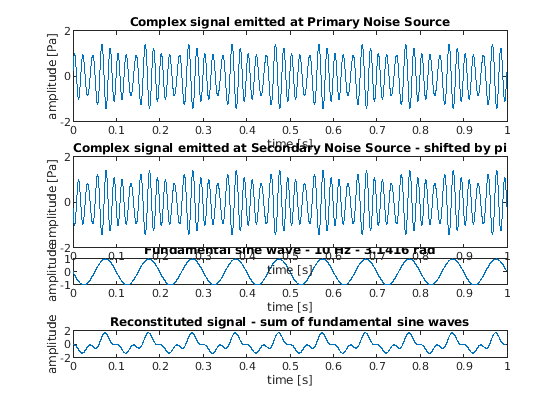

subplot(312);
plot(t,S2_wave);
title("Complex signal emitted at Secondary Noise Source - shifted by pi");
xlabel("time [s]"); ylabel("amplitude [Pa]");

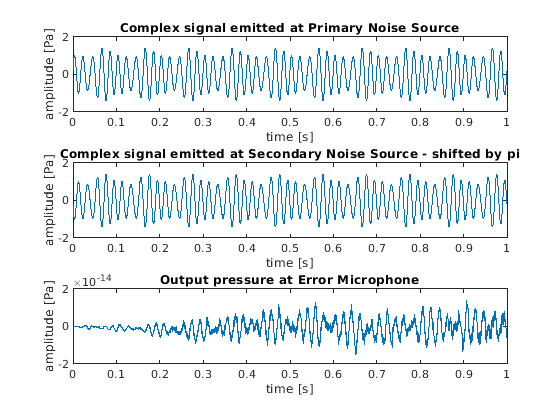

subplot(313);
plot(t,R_out_p);
title("Output pressure at Error Microphone");
xlabel("time [s]"); ylabel("amplitude [Pa]");

The output pressure at the error microphone is very small 10e-15 thus we suspect the experiment successful.

### LMS with wave decomposition

We will run the lms algorithm again and study what the wave decomposition of the output signal is at each step, to get an idea of what signal needs to be produced by the secondary noise in order to get a meaninful result after feeding it into the image source model.